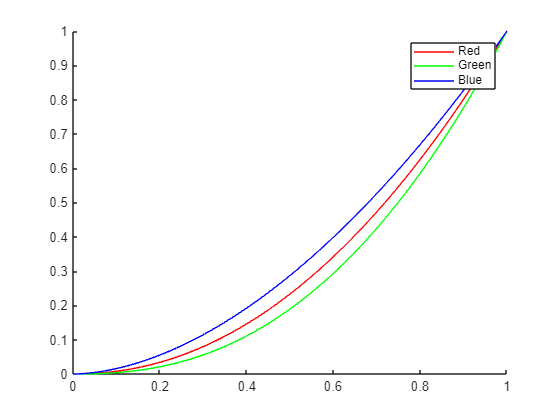

%1.1
clear
load("TRC_display.mat")
colorRange=0:0.01:1;
hold on
plot(colorRange,TRCr,"r")
plot(colorRange,TRCg,"g")
plot(colorRange,TRCb,"b")
legend("Red","Green","Blue")
hold off

Answer: Since the order of the values is quite off

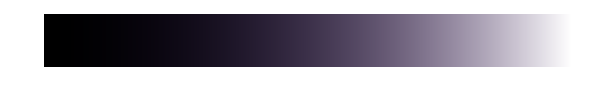

%1.2
load("Ramp_display.mat")
load("Ramp_linear.mat")
imshow(Ramp_display)

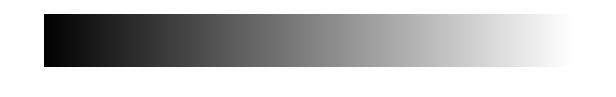

imshow(Ramp_linear)

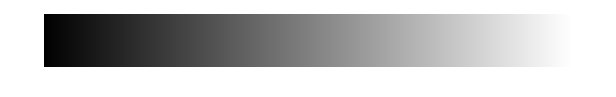


yr=interp1(TRCr,colorRange,Ramp_display(:,:,1),'pchip');
yg=interp1(TRCg,colorRange,Ramp_display(:,:,2),'pchip');
yb=interp1(TRCb,colorRange,Ramp_display(:,:,3),'pchip');

Ramp_display_Corrected=cat(3,yr,yb,yg);
save("Ramp_displayCorrected.mat","Ramp_display_Corrected")
imshow(Ramp_display_Corrected);

Ramp is now neutral. It's not identical but the color is corrected

%1.3
load("Ramp_displayCorrected.mat");
load("Ramp_display.mat")
yr=2,1;

yr = 2

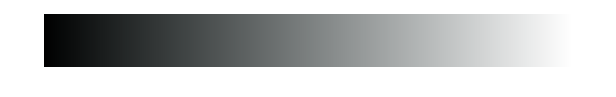

yg=2.4;
yb=1.8;
RampCorGamma=cat(3,Ramp_display(:,:,1).^(1/yr), Ramp_display(:,:,2).^(1/yg),Ramp_display(:,:,3).^(1/yb));
imshow(RampCorGamma)

Ramp is now seemingly linear, going from black to color.

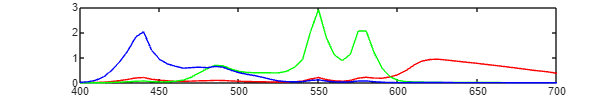

%2.1
clear
load("DLP.mat")
ramp=400:5:700;

plot(ramp,DLP(:,1),"r")
hold on
plot(ramp,DLP(:,2),"g")
plot(ramp,DLP(:,3),"b")
hold off

Projector has bad representation of red, but heavy rep for blue and ever heavier for green.

%2.2
load("RGB_raw.mat")
load("xyz.mat")
load("XYZ_ref.mat")
load("illum.mat")

Srgb=DLP*RGB_raw;
k=(100/(CIED65*(xyz(:,2))));
Sxyz=(k*Srgb'*xyz)';
[resMax,resMean]=meanSquare(Sxyz,XYZ_ref)

diff_REF_CAL =    23.2314   19.8215    6.6229   10.7843   19.3425   11.1055   51.6380   12.9531   49.1197    9.3144   20.5155   28.6191   18.2980   31.6065    5.5943   17.1405   14.5327   33.7034   46.8862   16.1867


resMax = 51.6380

resMean = 22.3508

%Convert Srgb values to Sxyz

Answer: They're seemingly on average quite of.

%2.3
load("RGB_cal.mat")
Srgb=DLP*RGB_cal;
k=(100/(CIED65*(xyz(:,2))));
Sxyz=(k*Srgb'*xyz)';
[resMax,resMean]=meanSquare(Sxyz,XYZ_ref)

diff_REF_CAL =    11.3933   14.2255   10.5205   11.0705   13.0698   10.5281   33.5351    8.6783   33.4318    5.4378   19.8112   16.1086   12.5781   16.1138   23.4782   19.0947   22.1049   20.3414   27.1078    9.8415


resMax = 33.5351

resMean = 16.9236

Answer: The calibrated seemingly give a better result, with a lower mean, but slightly higher max.

%3.1
clear
load("DLP.mat")
load("xyz.mat")
load("illum.mat")

k=100/(CIED65*(xyz(:,2)));

Acrt=k*xyz'*DLP

Acrt =    38.0922   55.7160   19.9274
   22.6080   87.9484   11.4011
   10.9203   16.5373   92.4433


%3.2
load("XYZ_est.mat")
load("XYZ_ref.mat")
D=pinv(Acrt)*XYZ_est;
Srgb=DLP*D;
Sxyz=(k*Srgb'*xyz)';

[resMax,resMean]=meanSquare(Sxyz,XYZ_ref)

diff_REF_CAL =     0.0337    2.3631    1.6165    1.1127    0.3276    1.0344    0.9939    0.2794    0.8178    1.5029    3.1053    1.4415    1.4043    0.9943    0.1533    0.8119    0.1666    0.9143    0.6314    0.7719


resMax = 3.1053

resMean = 1.0238

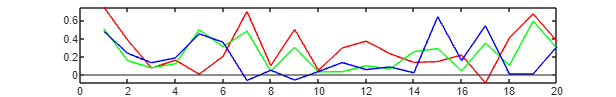

%3.3
plot(D(1,:), 'r');
hold on
plot(D(2,:), 'g');
plot(D(3,:), 'b');
yline(0);
hold off

min(D);
%Negative values?

%3.4
D(D<0)=0;
D(D>1)=1;
Srgb=DLP*D;
Sxyz=(k*Srgb'*xyz)';

[resMax,resMean]=meanSquare(Sxyz,XYZ_ref)

diff_REF_CAL =     0.0337    2.3631    1.6165    1.1127    0.3276    1.0344   13.1729    0.2794   17.8740    1.5029    3.1053    1.4415    1.4043    0.9943    0.1533    0.8119    7.1737    0.9143    0.6314    0.7719


resMax = 17.8740

resMean = 2.8360

%Performed worse? Less info? Färger som hamnat utanför färgomfånget

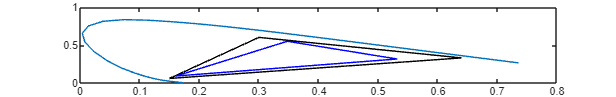

%3.5
plot_chrom_sRGB(Acrt)


%Within the projector space but far from utilizing it fully. Green
%is slightly off and Red is far off.


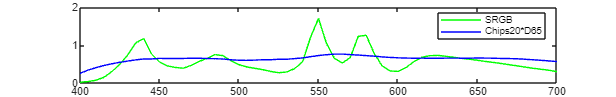

%3.6
load("chips20.mat")
clf
range=400:5:700;

plot(range,Srgb(:,1),"g")
hold on
plot(range,chips20(1,:).*CIED65, 'b');

legend('SRGB','Chips20*D65')